modulations = {'QPSK', '16QAM', '64QAM'};
colors = {'b', 'r', 'g'};
figure;
hold on;
for k = 1:length(modulations)
    modulation = modulations{k};
    BERs = [];
    SNRs = [];
    for SNRdB = -10:50    
        SNRdB% SNR in dB
        totalNoSlots = 100;         % Number of slots to simulate
        perfectEstimation = false; % Perfect synchronization and channel estimation
        rng("default");            % Set default random number generator for repeatability
        carrier = nrCarrierConfig;
        carrier.SubcarrierSpacing = 30;
        carrier.NSizeGrid = 52;
        pdsch = nrPDSCHConfig;
        pdsch.Modulation = modulations{k}; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        pdsch.NumLayers = 1;
        pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % Full band allocation
        pdsch.MappingType = 'A';
        pdsch.DMRS.DMRSAdditionalPosition = 1;
        pdsch.DMRS.DMRSConfigurationType = 1;
        pdsch.DMRS.DMRSLength = 2;
        pdsch.DMRS.DMRSTypeAPosition = 2;
        NHARQProcesses = 16;     % Number of parallel HARQ processes
        rvSeq = [0 2 3 1];
        % Coding rate
        if pdsch.NumCodewords == 1
            codeRate = 490/1024;
        else
            codeRate = [490 490]./1024;
        end
        
        % Create DL-SCH encoder object
        encodeDLSCH = nrDLSCH;
        encodeDLSCH.MultipleHARQProcesses = true;
        encodeDLSCH.TargetCodeRate = codeRate;
        
        % Create DLSCH decoder object
        decodeDLSCH = nrDLSCHDecoder;
        decodeDLSCH.MultipleHARQProcesses = true;
        decodeDLSCH.TargetCodeRate = codeRate;
        decodeDLSCH.LDPCDecodingAlgorithm = "Normalized min-sum";
        decodeDLSCH.MaximumLDPCIterationCount = 6;
        harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);
        
        nTxAnts = 1;
        nRxAnts = 1;
        
        % Check that the number of layers is valid for the number of antennas
        if pdsch.NumLayers > min(nTxAnts,nRxAnts)
            error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
        end
        
        channel = nrTDLChannel;
        channel.DelayProfile = "TDL-C";
        channel.NumTransmitAntennas = nTxAnts;
        channel.NumReceiveAntennas = nRxAnts;
        ofdmInfo = nrOFDMInfo(carrier);
        channel.SampleRate = ofdmInfo.SampleRate;
        constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
        constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
        constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements
        
        % Initial timing offset
        offset = 0;
        
        estChannelGrid = getInitialChannelEstimate(channel,carrier);
        newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);
        
        for nSlot = 0:totalNoSlots-1
            % New slot
            carrier.NSlot = nSlot;
            % Generate PDSCH indices info, which is needed to calculate the transport
            % block size
            [pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);
        
            % Calculate transport block sizes
            Xoh_PDSCH = 0;
            trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);
            % Get new transport blocks and flush decoder soft buffer, as required
            for cwIdx = 1:pdsch.NumCodewords
                if harqEntity.NewData(cwIdx)
                    % Create and store a new transport block for transmission
                    trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                    setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
        
                    % If the previous RV sequence ends without successful
                    % decoding, flush the soft buffer
                    if harqEntity.SequenceTimeout(cwIdx)
                        resetSoftBuffer(decodeDLSCH,cwIdx-1,harqEntity.HARQProcessID);
                    end
                end
            end
            codedTrBlock = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers,pdschInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlock);
            precodingWeights = newPrecodingWeight;
            pdschSymbolsPrecoded = pdschSymbols*precodingWeights;
            dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
            dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
            pdschGrid = nrResourceGrid(carrier,nTxAnts);
            [~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
            pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;
            % PDSCH DM-RS precoding and mapping
            for p = 1:size(dmrsSymbols,2)
                [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
                pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*precodingWeights(p,:);
            end
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            doppler = [-0.01383179+0.01512892j, 0.09733356-0.24178922j, 0.65802762-0.j, -0.05917827-0.01407249j, -0.0+0.0j];
        
            pdschGrid_prim = zeros(size(pdschGrid));
            for col = 1:size(pdschGrid, 2)
                pdschGrid_prim(:, col) = conv(pdschGrid(:, col), doppler, 'same');
            end
            [txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid_prim);
            chInfo = info(channel);
            maxChDelay = chInfo.MaximumChannelDelay;
            txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
            [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
            noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));
            rxWaveform = rxWaveform + noise;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            if perfectEstimation
                % Get path filters for perfect timing estimation
                pathFilters = getPathFilters(channel); 
                [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
            else
                [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
                offset = hSkipWeakTimingOffset(offset,t,mag);
            end
            rxWaveform = rxWaveform(1+offset:end,:);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        
            % Keep every fourth value from pdschGrid and zero the rest
            pdschGrid_filtered = zeros(size(pdschGrid));
            pdschGrid_filtered(4:4:end, :) = pdschGrid(4:4:end, :);
            
            % Initialize the correlation vector
            correlation_vector = zeros(size(rxGrid, 2), 5);
            
            % Compute correlation of respective pdschGrid and rxGrid columns, add correlations together
            for i = 1:size(rxGrid, 2)
                [correlation_vector(i, :), r] = xcorr(rxGrid(:, i), pdschGrid_filtered(:, i), 2, 'none');
            end
            
            correlation_vector = mean(correlation_vector, 1);
            correlation_vector = correlation_vector / correlation_vector(3);
            correlation_vector = correlation_vector / sum(abs(correlation_vector));
            %correlation_vector = padarray(correlation_vector, [0, 20], 'both');
        
            n = floor(size(correlation_vector)/2);
        
            zoom = circshift(correlation_vector,n+1);
            time_domain = ifft(zoom);
            time_domain = 1./time_domain;
            inverse_filter = fft(time_domain);
            inverse_filter = circshift(inverse_filter,n);
            
            %inverse_doppler = [-7.38892808e-06-1.60354388e-06j,  6.72579148e-06+1.72421308e-05j, 2.60724301e-05-3.70476251e-05j, -1.10847847e-04-3.06137316e-06j, 1.43726689e-04+2.30259541e-04j,  2.75249657e-04-6.04716525e-04j, -1.60595545e-03+2.56671414e-04j,  2.69635895e-03+2.92871245e-03j, 2.32621963e-03-9.46268215e-03j, -2.24501095e-02+8.05729568e-03j, 4.68098832e-02+3.48946871e-02j,  7.84998200e-03-1.42697871e-01j, -3.01708905e-01+1.77049924e-01j,  7.69359689e-01+3.75914008e-01j, -2.74081384e-01-2.07800331e+00j, -3.86809002e+00+3.37053480e+00j, 1.21087953e+01+3.33039411e+00j, -9.58960865e+00-2.92053948e+01j, -4.66076536e+01+5.90912748e+01j,  1.83557063e+02+1.53536412e+01j, -2.17005887e+02-3.92125305e+02j, -4.98541561e+02+1.01378236e+03j, 2.94361875e+03+1.61208981e+02j,  2.53515652e+02+8.29306180e+01j, 2.02189895e+01+1.31772963e+01j,  1.45906445e+00+1.62460233e+00j, 8.95355347e-02+1.76119717e-01j,  3.70703426e-03+1.74875686e-02j, -8.49569981e-05+1.61518703e-03j, -4.51987997e-05+1.39187899e-04j, -7.20567022e-06+1.11086173e-05j, -8.89611875e-07+8.02454462e-07j, -9.64540182e-08+4.93299244e-08j, -9.68405733e-09+1.92100691e-09j, -1.03169739e-09+3.27908145e-10j,  8.80544526e-10-2.31922925e-10j, -1.72342851e-09-1.67572978e-09j, -1.08742881e-09+5.76470871e-09j, 1.32309737e-08-5.58262059e-09j, -2.92885147e-08-1.94366407e-08j, -2.28983776e-11+8.60422758e-08j,  1.75547943e-07-1.16364339e-07j, -4.74878074e-07-2.00663894e-07j,  2.33153425e-07+1.24018824e-06j, 2.21440546e-06-2.15352018e-06j];
            inverse_doppler = inverse_filter;
            %inverse_doppler = [1, ];
        
            rxGrid_prim = zeros(size(rxGrid));
            for col = 1:size(rxGrid, 2)
                rxGrid_prim(:, col) = conv(rxGrid(:, col), inverse_doppler, 'same');
            end
            rxGrid = rxGrid_prim;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
            if perfectEstimation
                % Perform perfect channel estimation between transmit and receive
                % antennas.
                estChGridAnts = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
        
                % Get perfect noise estimate (from noise realization)
                noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
                noiseEst = var(noiseGrid(:));
        
                % Get precoding matrix for next slot
                newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChGridAnts);
        
                % Apply precoding to estChGridAnts. The resulting estimate is for
                % the channel estimate between layers and receive antennas.
                estChGridLayers = precodeChannelEstimate(estChGridAnts,precodingWeights.');
            else
                % Perform practical channel estimation between layers and receive
                % antennas.
                [estChGridLayers,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
        
                % Remove precoding from estChannelGrid before precoding
                % matrix calculation
                estChGridAnts = precodeChannelEstimate(estChGridLayers,conj(precodingWeights));
        
                % Get precoding matrix for next slot
                newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChGridAnts);
            end
        
            %mesh(abs(estChGridLayers(:,:,1,1)));
            %title('Channel Estimate');
            %xlabel('OFDM Symbol');
            %ylabel("Subcarrier");
            %zlabel("Magnitude");
            [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChGridLayers);
            [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
            %constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
            %constPlot.ShowLegend = true;
            % Constellation for the first layer has a higher SNR than that for the
            % last layer. Flip the layers so that the constellations do not mask
            % each other.
            %constPlot(fliplr(pdschEq));
        
            [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
        
            % Scale LLRs by CSI
            csi = nrLayerDemap(csi);                                    % CSI layer demapping
            for cwIdx = 1:pdsch.NumCodewords
                Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % Bits per symbol
                csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % Expand by each bit per symbol
                dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % Scale
            end
        
            decodeDLSCH.TransportBlockLength = trBlkSizes;
            [decbits,blkerr] = decodeDLSCH(dlschLLRs,pdsch.Modulation,pdsch.NumLayers, ...
                harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            
            statusReport = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschInfo.G);    
            %disp("Slot "+(nSlot)+". "+statusReport);
        end % for nSlot = 0:totalNoSlots
        
        
        good = 0;
        total = 0;
        input_symbols = pdschSymbols;
        estimated = pdschEq;
        
        if strcmp(modulation, 'BPSK')
            for i = 1:length(input_symbols)
                x = input_symbols(i);
                y = estimated(i);
                total = total + 1;
                if real(x) * real(y) > 0
                    good = good + 1;
                end
            end
        
        elseif strcmp(modulation, 'QPSK')
            average_power = mean(abs(estimated .* estimated));
            scale = sqrt(2) / sqrt(average_power);
            constellation = estimated * scale;
            average_power = mean(abs(input_symbols .* input_symbols));
            scale = sqrt(2) / sqrt(average_power);
            input_symbols = input_symbols * scale;
            for i = 1:length(input_symbols)
                x = input_symbols(i);
                y = estimated(i);
                total = total + 2;
                if real(x) * real(y) > 0
                    good = good + 1;
                end
                if imag(x) * imag(y) > 0
                    good = good + 1;
                end
            end
        
        elseif strcmp(modulation, '16QAM')
            average_power = mean(abs(estimated .* estimated));
            scale = sqrt(10) / sqrt(average_power);
            constellation = estimated * scale;
            average_power = mean(abs(input_symbols .* input_symbols));
            scale = sqrt(10) / sqrt(average_power);
            input_symbols = input_symbols * scale;
            for i = 1:length(input_symbols)
                x = input_symbols(i);
                y = constellation(i);
                total = total + 4;
                if real(x) * real(y) > 0
                    good = good + 1;
                end
                if imag(x) * imag(y) > 0
                    good = good + 1;
                end
                if (0 < real(x) && real(x) < 2 || real(x) < -2) && (0 < real(y) && real(y) < 2 || real(y) < -2)
                    good = good + 1;
                end
                if (0 > real(x) && real(x) > -2 || real(x) > 2) && (0 > real(y) && real(y) > -2 || real(y) > 2)
                    good = good + 1;
                end
                if (0 < imag(x) && imag(x) < 2 || imag(x) < -2) && (0 < imag(y) && imag(y) < 2 || imag(y) < -2)
                    good = good + 1;
                end
                if (0 > imag(x) && imag(x) > -2 || imag(x) > 2) && (0 > imag(y) && imag(y) > -2 || imag(y) > 2)
                    good = good + 1;
                end
            end
        
        elseif strcmp(modulation, '64QAM')
            average_power = mean(abs(estimated .* estimated));
            scale = sqrt(42) / sqrt(average_power);
            constellation = estimated * scale;
            average_power = mean(abs(input_symbols .* input_symbols));
            scale = sqrt(42) / sqrt(average_power);
            input_symbols = input_symbols * scale;
            for i = 1:length(input_symbols)
                x = input_symbols(i);
                y = constellation(i);
                total = total + 6;
                if real(x) * real(y) > 0
                    good = good + 1;
                end
                if imag(x) * imag(y) > 0
                    good = good + 1;
                end
                if -4 < real(x) && real(x) < 4 && -4 < real(y) && real(y) < 4
                    good = good + 1;
                elseif (real(x) > 4 || real(x) < -4) && (real(y) > 4 || real(y) < -4)
                    good = good + 1;
                end
                if -4 < imag(x) && imag(x) < 4 && -4 < imag(y) && imag(y) < 4
                    good = good + 1;
                elseif (imag(x) > 4 || imag(x) < -4) && (imag(y) > 4 || imag(y) < -4)
                    good = good + 1;
                end
                if (-6 > real(x) || -2 < real(x) && real(x) < 2 || 6 < real(x)) && (-6 > real(y) || -2 < real(y) && real(y) < 2 || 6 < real(y))
                    good = good + 1;
                elseif (2 < real(x) && real(x) < 6 || -6 < real(x) && real(x) < -2) && (2 < real(y) && real(y) < 6 || -6 < real(y) && real(y) < -2)
                    good = good + 1;
                end
                if (-6 > imag(x) || -2 < imag(x) && imag(x) < 2 || 6 < imag(x)) && (-6 > imag(y) || -2 < imag(y) && imag(y) < 2 || 6 < imag(y))
                    good = good + 1;
                elseif (2 < imag(x) && imag(x) < 6 || -6 < imag(x) && imag(x) < -2) && (2 < imag(y) && imag(y) < 6 || -6 < imag(y) && imag(y) < -2)
                    good = good + 1;
                end
            end
        end
        
        BER = 1 - good / total;
        BERs = [BERs, BER];
        SNRs = [SNRs, SNRdB];
    end
    semilogy(SNRs, BERs, 'Color', colors{k}, 'DisplayName', modulation);
end

SNRdB = -10

SNRdB = -9

SNRdB = -8

SNRdB = -7

SNRdB = -6

SNRdB = -5

SNRdB = -4

SNRdB = -3

SNRdB = -2

SNRdB = -1

SNRdB = 0

SNRdB = 1

SNRdB = 2

SNRdB = 3

SNRdB = 4

SNRdB = 5

SNRdB = 6

SNRdB = 7

SNRdB = 8

SNRdB = 9

SNRdB = 10

SNRdB = 11

SNRdB = 12

SNRdB = 13

SNRdB = 14

SNRdB = 15

SNRdB = 16

SNRdB = 17

SNRdB = 18

SNRdB = 19

SNRdB = 20

SNRdB = 21

SNRdB = 22

SNRdB = 23

SNRdB = 24

SNRdB = 25

SNRdB = 26

SNRdB = 27

SNRdB = 28

SNRdB = 29

SNRdB = 30

SNRdB = 31

SNRdB = 32

SNRdB = 33

SNRdB = 34

SNRdB = 35

SNRdB = 36

SNRdB = 37

SNRdB = 38

SNRdB = 39

SNRdB = 40

SNRdB = 41

SNRdB = 42

SNRdB = 43

SNRdB = 44

SNRdB = 45

SNRdB = 46

SNRdB = 47

SNRdB = 48

SNRdB = 49

SNRdB = 50

SNRdB = -10

SNRdB = -9

SNRdB = -8

SNRdB = -7

SNRdB = -6

SNRdB = -5

SNRdB = -4

SNRdB = -3

SNRdB = -2

SNRdB = -1

SNRdB = 0

SNRdB = 1

SNRdB = 2

SNRdB = 3

SNRdB = 4

SNRdB = 5

SNRdB = 6

SNRdB = 7

SNRdB = 8

SNRdB = 9

SNRdB = 10

SNRdB = 11

SNRdB = 12

SNRdB = 13

SNRdB = 14

SNRdB = 15

SNRdB = 16

SNRdB = 17

SNRdB = 18

SNRdB = 19

SNRdB = 20

SNRdB = 21

SNRdB = 22

SNRdB = 23

SNRdB = 24

SNRdB = 25

SNRdB = 26

SNRdB = 27

SNRdB = 28

SNRdB = 29

SNRdB = 30

SNRdB = 31

SNRdB = 32

SNRdB = 33

SNRdB = 34

SNRdB = 35

SNRdB = 36

SNRdB = 37

SNRdB = 38

SNRdB = 39

SNRdB = 40

SNRdB = 41

SNRdB = 42

SNRdB = 43

SNRdB = 44

SNRdB = 45

SNRdB = 46

SNRdB = 47

SNRdB = 48

SNRdB = 49

SNRdB = 50

SNRdB = -10

SNRdB = -9

SNRdB = -8

SNRdB = -7

SNRdB = -6

SNRdB = -5

SNRdB = -4

SNRdB = -3

SNRdB = -2

SNRdB = -1

SNRdB = 0

SNRdB = 1

SNRdB = 2

SNRdB = 3

SNRdB = 4

SNRdB = 5

SNRdB = 6

SNRdB = 7

SNRdB = 8

SNRdB = 9

SNRdB = 10

SNRdB = 11

SNRdB = 12

SNRdB = 13

SNRdB = 14

SNRdB = 15

SNRdB = 16

SNRdB = 17

SNRdB = 18

SNRdB = 19

SNRdB = 20

SNRdB = 21

SNRdB = 22

SNRdB = 23

SNRdB = 24

SNRdB = 25

SNRdB = 26

SNRdB = 27

SNRdB = 28

SNRdB = 29

SNRdB = 30

SNRdB = 31

SNRdB = 32

SNRdB = 33

SNRdB = 34

SNRdB = 35

SNRdB = 36

SNRdB = 37

SNRdB = 38

SNRdB = 39

SNRdB = 40

SNRdB = 41

SNRdB = 42

SNRdB = 43

SNRdB = 44

SNRdB = 45

SNRdB = 46

SNRdB = 47

SNRdB = 48

SNRdB = 49

SNRdB = 50

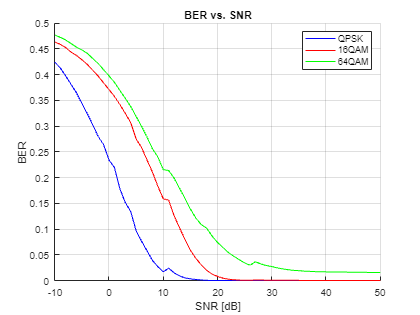

hold off; % Release the plot hold
xlabel('SNR [dB]'); % Replace with appropriate label
ylabel('BER'); % Replace with appropriate label
title('BER vs. SNR');
legend('show'); % Display the legend
grid on;

    function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
    % Generate AWGN for a given value of SNR in dB (SNRDB), which is the
    % receiver SNR per RE and antenna, assuming the channel does
    % not affect the power of the signal. NRXANTS is the number of receive
    % antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
    % is the size of the receive waveform used to calculate the size of the
    % noise matrix.
    
        % Normalize noise power by the IFFT size used in OFDM modulation, as
        % the OFDM modulator applies this normalization to the transmitted
        % waveform. Also normalize by the number of receive antennas, as the
        % channel model applies this normalization to the received waveform by
        % default. The SNR is defined per RE for each receive antenna (TS
        % 38.101-4).
        SNR = 10^(SNRdB/10); % Calculate linear noise gain
        N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
        noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
    end
        
    function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
    % Calculate precoding matrix given an allocation and a channel estimate
        
        % Allocated subcarrier indices
        allocSc = (1:12)' + 12*PRBSet(:).';
        allocSc = allocSc(:);
        
        % Average channel estimate
        [~,~,R,P] = size(hestGrid);
        estAllocGrid = hestGrid(allocSc,:,:,:);
        Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
        
        % SVD decomposition
        [~,~,V] = svd(Hest);
        
        wtx = V(:,1:NLayers).';
        wtx = wtx/sqrt(NLayers); % Normalize by NLayers
    end
    
    function estChannelGrid = getInitialChannelEstimate(channel,carrier)
    % Obtain an initial channel estimate for calculating the precoding matrix.
    % This function assumes a perfect channel estimate
    
        % Clone of the channel
        chClone = channel.clone();
        chClone.release();
    
        % No filtering needed to get channel path gains
        chClone.ChannelFiltering = false;    
        
        % Get channel path gains
        [pathGains,sampleTimes] = chClone();
        
        % Perfect timing synchronization
        pathFilters = getPathFilters(chClone);
        offset = nrPerfectTimingEstimate(pathGains,pathFilters);
        
        % Perfect channel estimate
        estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
    end
    
    function refPoints = getConstellationRefPoints(mod)
    % Calculate the reference constellation points for a given modulation
    % scheme.
        switch mod
            case "QPSK"
                nPts = 4;
            case "16QAM"
                nPts = 16;
            case "64QAM"
                nPts = 64;
            case "256QAM"
                nPts = 256;            
        end
        binaryValues = int2bit(0:nPts-1,log2(nPts));
        refPoints = nrSymbolModulate(binaryValues(:),mod);
    end
    
    function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
    % Apply precoding matrix W to the last dimension of the channel estimate.
    
        % Linearize 4-D matrix and reshape after multiplication
        K = size(estChannelGrid,1);
        L = size(estChannelGrid,2);
        R = size(estChannelGrid,3);
        estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
        estChannelGrid = estChannelGrid*W;
        estChannelGrid = reshape(estChannelGrid,K,L,R,[]);
    
    end